%FFT

Nfft = 2^20;
xfft = fs*(0:Nfft/2)/Nfft

xfft = 	1.0e+06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004



win = blackman(n);
win = win';

v = out.v

v =      0
     1
    -1
    -1
     1
    -1
     1
     1
    -1
     1


v = v'

v =      0     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1    -1     1    -1    -1     1     1    -1     1    -1     1    -1     1    -1     1     1    -1    -1     1    -1     1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1


v1 = v.*win

v1 =          0    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000


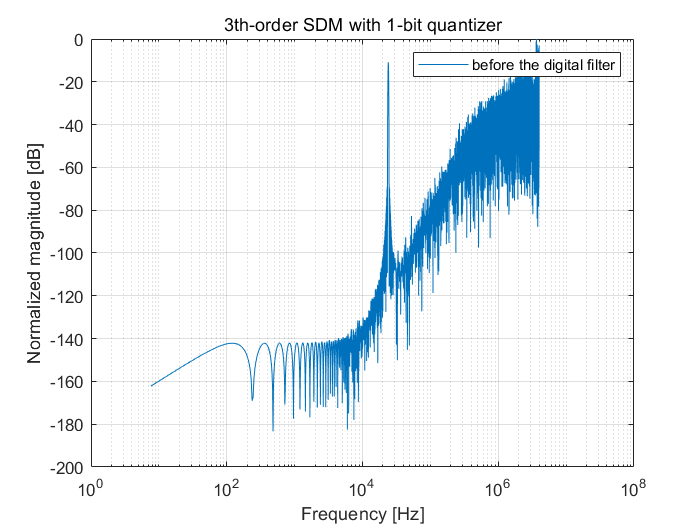


Y = fft(v1,Nfft);
%Y = fft(X,n) 返回 n 点 DFT。如果未指定任何值，则 Y 的大小与 X 相同。
%如果 X 是向量且 X 的长度小于 n，则为 X 补上尾零以达到长度 n
P2 = abs(Y/Nfft);
P1 = P2(1:Nfft/2+1);
P1(2:end-1) = P1(2:end-1)*2;

V1 = Y(1:Nfft/2+1);

figure;
semilogx(xfft,20*log10(abs(V1/max(V1))));

% semilogx(xfft,P1);
hold on;

legend('before the digital filter');
grid on;

xlabel('Frequency [Hz]');
ylabel('Normalized magnitude [dB]');
title(['3th-order SDM with 1-bit quantizer']);